# Exercise for Week 5 - Parameter estimation for multi-dimensional Gaussian mixture models using Expectation-Maximisation (EM) Algorithm

Please complete the code in **Fit a GMM to the dataset using the EM Algorithm **chapter in this exercise. You implementation of the EM Algorithm should work on the 3 datasets generated at the beginning of the worksheet. The following information may benefit your practice.

- The Probability Density Function (PDF) of a multivariate GMM is given as,


$$p\left(x\right)=\sum_k^K \pi_{k\;} \cdot p\left(x|\mu_k \;,\Sigma_k \;\right)$$


- The new objective function in the EM Algorithm replaces the objective function in the MLE.


$$Q\left(\Theta \right)=\sum_n {\mathbb{E}}_{z~p\left(z|x\right)} \;\ln \;p\left(x,z\right)$$


## Datasets generation  (Do not change anything in this chapter!)

Dataset 1 - A 2-dimensional dataset generated by 6 different Gaussian distributions.

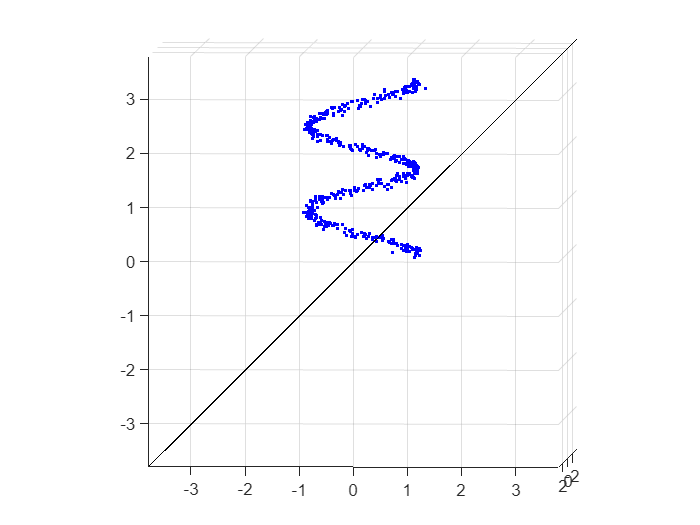

clc, clear
%% Parameters used to generate observations
mu = [1 2;-3 -5;-4 4;6 8;5 -5];                                      % Means
sigma = cat(3,[2 0;0 .5],[1 0;0 1],[2 0;0 2],[2 0;0 .5],[1 0;0 1]);              % Covariances
prior = ones(1,5)/2;                                        % Mixing co-efficients
%% Generate the PDF of the GMM
gm = gmdistribution(mu,sigma,prior);
%% Plot the defined PDF in 3D
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(gm,[x0 y0]), x, y);
fs = fsurf(gmPDF, [-10 10], FaceAlpha=0.6);
colormap(sky); 

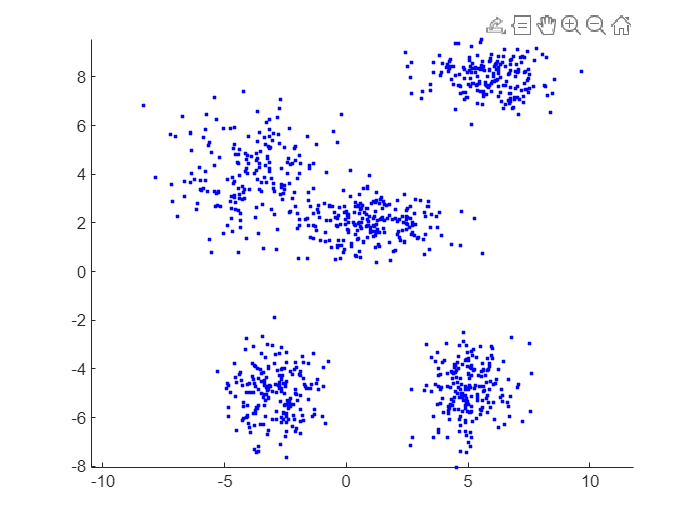

%% Generate 1000 samples
DataX1 = random(gm, 1000);
%% Plot samples
figure;
scatter(DataX1(:,1), DataX1(:,2), '.b')
axis equal

Dataset 2 - A 3-dimensional spiral dataset simulating the observation of a trajectory. 

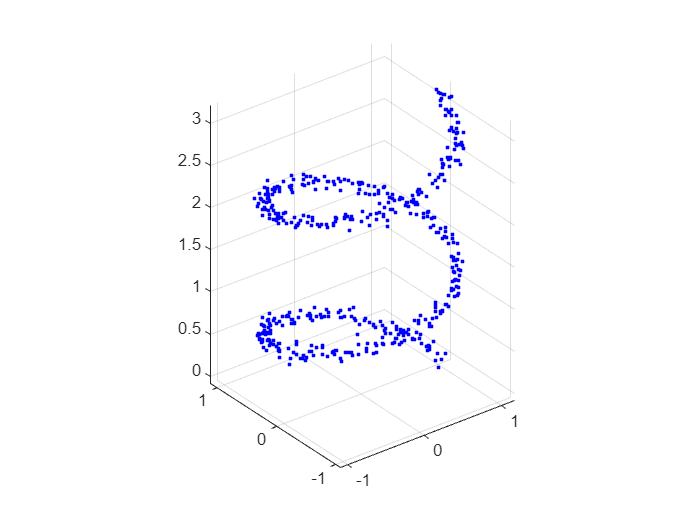

% Define the parameter 't' over which the spiral is generated
num_points = 500;                                  % 500 points
noiseFactor = 0.05;  % Define noise factor (adjust this to control the noise amplitude)
t = repmat(linspace(0, 2*pi, num_points/5),1,5);   % points from 0 to 6*pi
% Calculate the x, y, and z coordinates for the spiral
x = cos(2*t) + noiseFactor * randn(size(t));    % x-coordinate: cosine function
y = sin(2*t) + noiseFactor * randn(size(t));    % y-coordinate: sine function
z = 0.5*t + noiseFactor * randn(size(t));         % z-coordinate: linear progression to create the spiral effect
% Combine all dimensions into a single dataset
DataX2 = [x;y;z]';
% Create a 3D plot of the spiral
figure;
scatter3(DataX2(:,1), DataX2(:,2), DataX2(:,3), '.b'); hold on;
axis equal

Dataset 3 - A 5-dimensional dataset generated by 3 different multivariate Gaussian distributions. The plot only show the first 3 dimension of the dataset, because scatter diagram cannot visualise data more than 3D.

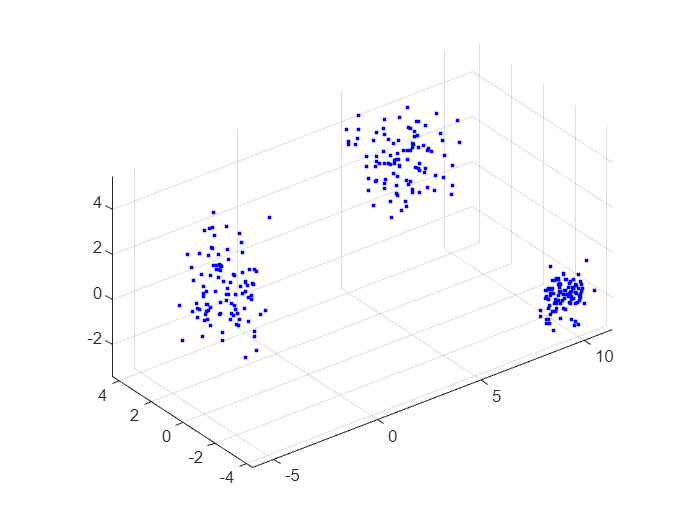

% Define the number of dimensions and samples per Gaussian
dim = 5;          % Dimensionality of the data
num_samples = 100; % Number of samples per Gaussian distribution
% Define mean vectors for three Gaussian distributions
mu1 = [6, 2, 3, 4, 5];   % Mean of the first Gaussian
mu2 = [-4, 0, 2, 4, -1]; % Mean of the second Gaussian
mu3 = [10, -3, -2, 0, 2];  % Mean of the third Gaussian
% Define covariance matrices for three Gaussians
sigma1 = eye(dim);              % Identity covariance matrix
sigma2 = diag([1,0.1,2,4,6]);   % Scaled covariance matrix 
sigma3 = 0.25 * eye(dim);       % Smaller variance
% Generate samples from the three Gaussian distributions
data1 = mvnrnd(mu1, sigma1, num_samples);
data2 = mvnrnd(mu2, sigma2, num_samples);
data3 = mvnrnd(mu3, sigma3, num_samples);
% Combine all samples into a single dataset
DataX3 = [data1; data2; data3];
% Plot the first three dimensions to visualize the clusters
figure;
scatter3(DataX3(:,1), DataX3(:,2), DataX3(:,3), '.b'); hold on;
axis equal

There are many datasets suitable for the GMM fitting. You can find more on this website🌐 [https://archive.ics.uci.edu/datasets](https://archive.ics.uci.edu/datasets). Try to download some for your exercise.

## Fit a GMM to the dataset using the EM Algorithm 

Set dataset and hyper-parameters. 👈👈👈

K = 18;   % Choose your Gaussian component number in your mixture  
X = DataX1;         % Change your dataset here         
[N, d] = size(X);   % N: number of samples, d: dimensionality of the data
maxIter = 100;      % Set maximum number of iterations
tol = 1e-6;         % Convergence tolerance for the log-likelihood

Parameter initialisation for the EM Algorithm. Compared with the Gradient Descent, the optimisation result from the EM Algorithm is less likely affected by the initialisation, but a good initialisation would reduce the converging time. Therefore, you are encouraged to try other initialisation methods in this chapter 

pi_k = ones(1, K) / K;      % Initialize mixing coefficients (weights) equally
randIdx = randperm(N, K);   % Randomly choose K data points as initial means (each column is a mean vector)
mu_k = X(randIdx, :)';      % d x K matrix
Sigma_k = repmat(eye(d), [1, 1, K]);    % Initialize covariance matrices to identity matrices
logLikelihood = -inf;       % Initialize log likelihood for convergence checking

EM loop.

figure;
for iter = 1:maxIter

**E-step:** Compute responsibilities for each data point and each component (Posterior).  👈👈👈


$$\gamma {\;}_{\mathrm{nk}} =p\left(z|x\right)=\frac{p\left(z\right)p\left(x|z\right)}{\sum_z p\left(z\right)p\left(x|z\right)}=\frac{\pi_{k\;} \mathcal{N}\;\left(x_n |\mu_{k\;} ,\Sigma {\;}_k \right)}{\sum_j \pi_j \mathcal{N}\;\left(x_n |\mu_j ,\Sigma_j \right)}$$


    gamma = zeros(N, K);      % Initialise posterior p(z|x)
    gamma = p(z|x) ;

**M-step:** Update the parameters of a K-component GMM using the responsibilities.  👈👈👈


$$\pi_k \;:=\frac{\sum_n \gamma {\;}_{\mathrm{nk}} }{N}$$



$$\mu_{k\;} :=\frac{\sum_n \gamma {\;}_{\mathrm{nk}} \;x_n }{\sum_n \gamma {\;}_{\mathrm{nk}} }$$



$$\Sigma {\;}_k :=\frac{\sum_n \gamma {\;}_{\mathrm{nk}} \left(x_n -\mu_k \right){\left(x_n -\mu_k \right)}^T }{\sum_n \gamma {\;}_{\mathrm{nk}} }$$


    % Calculate the effective number of points assigned to each component.
    N_k  ;

    % Update mixing coefficients.
    pi_k =  ;

    % Update means for each component.
    mu_k(:, k) = ;

    % Update covariance matrices for each component.
    Sigma_k(:, :, k) =  ;    % Weighted covariance calculation.

    Sigma_k(:, :, k) = Sigma_k(:, :, k) + 1e-6 * eye(d);       % Regularize covariance matrix to avoid singularity.

Compute the log likelihood for the current parameters.

    L = 0;
    for n = 1:N
        temp = 0;
        for k = 1:K
            temp = temp + pi_k(k) * mvnpdf(X(n, :), mu_k(:, k)', Sigma_k(:, :, k));
        end
        L = L + log(temp);
    end

Check for convergence: if the change in log-likelihood is below tolerance, stop iterating.

    if abs(L - logLikelihood) < tol
        fprintf('Convergence reached at iteration %d.\n', iter);
        break;
    end
    logLikelihood(iter) = L;
    fprintf('Iteration %d: Log-Likelihood = %.6f\n', iter, L);

Plot the GMM after each iteration.  

    % Plot 
    plotGmmAndData(mu_k,Sigma_k,X)
    title('GMM fitting using the EM Algorithm');
    grid on;
    axis equal;
    pause(0.1);
end

Invalid expression. Check for missing or extra characters.

Display the final parameters. 

disp('Final mixing coefficients:');
disp(pi_k);
disp('Final means (each column is a mean vector):');
disp(mu_k);
disp('Final covariance matrices:');
for k = 1:K
    fprintf('Component %d covariance matrix:\n', k);
    disp(Sigma_k(:, :, k));
end

Plot the data and the final estimated Gaussian components.

figure;
plotGmmAndData(mu_k,Sigma_k,X)
title('Optimalised GMM');
grid on;
axis equal;

Plot the Log-likelihood during the EM iteration.

figure;
plot(logLikelihood,'-r','LineWidth',2);
title('Log-likelihood during training');
xlabel('number of iterations')
ylabel('Log-likelihood')

## Useful functions (Add more functions if you need)

Plot samples with the GMM.

function plotGmmAndData(Mu,Sigma,X)
    data_dim = size(X,2);
    if data_dim == 1
        disp('Unable to plot the 1-d data!')
    elseif data_dim == 2
        scatter(X(:,1), X(:,2), 10, '.b'); hold on;
        plotGaussians(Mu,Sigma)
        hold off
    else
        scatter3(X(:,1), X(:,2), X(:,3), 10, '.b'); hold on;
        plotGaussians(Mu,Sigma)
        hold off
    end
end

## End of exercise